**This script prepares metadata for further analysis.**

**1. Load correct metadata **(copied from OLP4CBP/data/healthies_measures.mat and OLP4CBP/data/final_12mo_outcomes_wide.csv)

today = datestr(datetime("today"),'yymmdd'); % for saving files at the end

% load correct CBP data
CBP_correct_meta = readtable("Data/raw/final_12mo_outcomes_wide.csv");
CBP_cols = {'bpi_intensity_t1_arm_1', 'odi_t1_arm_1', ...
    'promis_dep_t1_arm_1', 'promis_anger_t1_arm_1', 'promis_anxiety_t1_arm_1', 'promis_sleep_t1_arm_1'};
CBP_final = CBP_correct_meta(:, CBP_cols);
CBP_final.id = CBP_correct_meta.id; % add id column
% remove arm from column names
CBP_final.Properties.VariableNames = regexprep(CBP_final.Properties.VariableNames,"_arm_1","");

% load correct healthies measures
load("Data/raw/healthies_measures.mat")
% add 9000 to HC ids -> this is how they are coded in the brainpathway metadata
healthies_measures.id = healthies_measures.id + 9000

healthies_measures = 55×17 table
     id     pain_avg    panas_pa    panas_na    bpi_intensity    bpi_interference    odi    pcs    promis_dep    promis_anger    promis_anxiety    promis_sleep    tsk11    sopa_emo    alcohol    opioid    cannabis
    ____    ________    ________    ________    _____________    ________________    ___    ___    __________    ____________    ______________    ____________    _____    ________    _______    ______

HC_final = healthies_measures(:, regexprep(CBP_cols,"_t1_arm_1",""));
% add t1 to column names
HC_final.Properties.VariableNames = append(HC_final.Properties.VariableNames, "_t1");
HC_final.id = healthies_measures.id; % add id column

% join promis data from CBP & HC vertically
meta_correct_merged = [CBP_final; HC_final]  % 198 rows

meta_correct_merged = 198×7 table
    bpi_intensity_t1    odi_t1    promis_dep_t1    promis_anger_t1    promis_anxiety_t1    promis_sleep_t1    id 
    ________________    ______    _____________    _______________    _________________    _______________    ___

           2.5            10           17                 9                  17                  30            23
           4.5            18           12                16                  15                  21            24
             4            16            8                 5                   8                  11            51
           4.5            14           11                12                  12                  23            61
          5.25            16            8  

Load metadata from the brainpathway object, subset revelant columns. **Check ID** **matches** between datasets, merge with the HC & CBP table.

Add **negative affect factor** and **high_motion_subject** column.

% load metadata from the brainpathway object
load("Data/raw/brainpathway_data_gsr_censoring_pipeline_nosmoothing.mat")
meta_bs = bs.subject_metadata(:, {'id', 'time', 'age', 'gender', 'education', 'ethnicity', 'hispanic', ...
    'employment_status', 'exercise', 'is_patient', 'backpain_length', 'n_spike_regs_sponpain'});

% add row index to sort after merging the correct metadata
meta_bs.row_index = (1:height(meta_bs))';

% check final_promis index against brainpathway metadata indices
setdiff(meta_correct_merged.id, meta_bs.id)  % in correct meta but not in brainpathway: 9013, 9017, 9033, 9052

ans =         9013
        9017
        9033
        9052


setdiff(meta_bs.id, meta_correct_merged.id) % in brainpathway but not in correct meta: 12, 14, 15, 18, 29, 32, 38, 69, 1004

ans =           12
          14
          15
          18
          29
          32
          38
          69
        1004


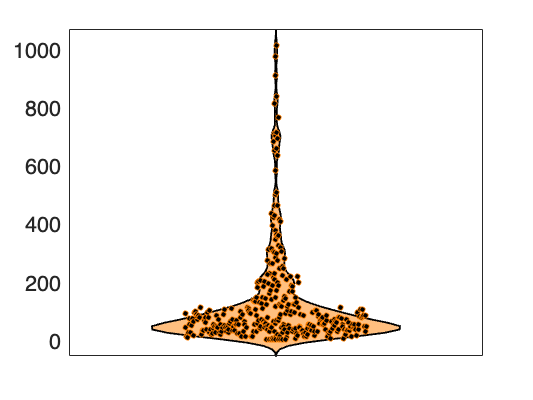



% merge correct CBP promis cols with all metadata
merged = outerjoin(meta_bs, meta_correct_merged, 'Keys', 'id', 'Type','Left', 'MergeKeys',true);
% sort rows by row_index => same ordering as the whole bs structure
merged = sortrows(merged, 'row_index');
% remove the row_index column
merged.row_index = [];

% add a negative affect factor
merged.negative_affect_t1 = mean(merged{:, {'promis_dep_t1', 'promis_anger_t1', 'promis_anxiety_t1'}}, 2);

% add column with motion outliers (>3std above the HC mean)
HC_motion_std = std(rmmissing(merged(merged.is_patient == 0,:).n_spike_regs_sponpain));

HC_motion_std = 66.2184

ans = 3×3 table
           is_patient    time    GroupCount
           __________    ____    __________

    0_1      false        1          49    
    1_1      true         1         120    
    1_2      true         2         109    


ans = 3×3 table
           is_patient    time    GroupCount
           __________    ____    __________

    0_1      false        1          51    
    1_1      true         1         151    
    1_2      true         2         135    


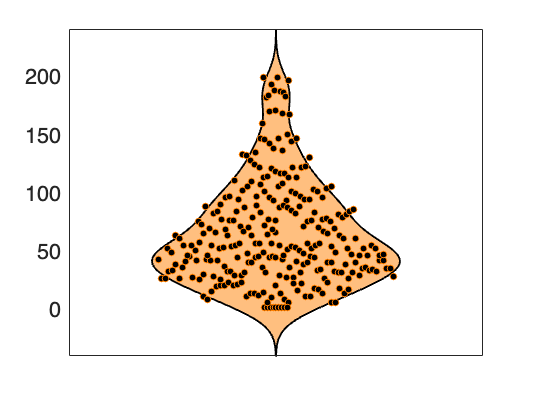

merged.high_motion_subject = merged.n_spike_regs_sponpain > HC_motion_std*3;

Save as a new brainpathway object to be used in HDI calculation & LMMs.

bs.subject_metadata = merged
save(['Data/raw/_brainpathway_data_with_correct_meta_' today], 'bs');
% writetable(merged, ['Data/', today '_metadata_prepped.csv']);